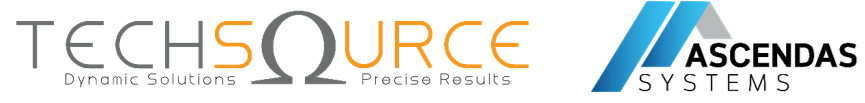

# Hands-On Workshop — IoT dengan Simulink, ThingSpeak & ESP32

## Model Simulink IoT Monitoring (ID)

**Metadata**

- **Durasi** — 120 menit (30 menit setup IoT + 40 menit membangun model + 30 menit deploy & data live + 20 menit tantangan)

- **Peserta** — Mahasiswa S1, latar belakang teknik (pemula hingga menengah)

- **Produk MATLAB** — MATLAB, Simulink, Embedded Coder *(sesuai laporan Dependency Analyzer MATLAB)*

- **Dukungan ESP32 (add-on)** — Simulink Support Package for Arduino Hardware — support package, bukan toolbox (`ver` tidak akan mendaftarnya)

- **Platform** — ThingSpeak (analytics IoT MathWorks) melalui MQTT + Wi-Fi

- **Target Hardware** — ESP32-WROOM (kompatibel Arduino) — 1 board per kelompok (3 orang)

- **Pengetahuan Prasyarat** — MATLAB dasar (variabel, script) dan Simulink dasar (blok, simulasi)

## 0. Gambaran Workshop

Pada workshop hands-on 2 jam ini Anda membangun sebuah **model Simulink® yang berjalan di ESP32**, membaca data sensor, dan mempublikasikannya secara live ke **kanal ThingSpeak™** melalui MQTT. Model ini juga memperlihatkan loop IoT yang lengkap: model membaca kembali kanalnya sendiri serta menggerakkan output fisik dan output simulasi.

**Sinyal · Sumber · Field ThingSpeak**

- **TemperatureData** — Analog input (atau knob simulasi) · **Field 1**

- **ThresholdData** — Analog input / knob threshold · **Field 2**

- **FanControl** — TemperatureData > ThresholdData · **Field 3**

Workshop dibagi menjadi enam fase:

- ✅ **Siapkan peralatan** — verifikasi produk MATLAB, pasang support package ESP32, dan hubungkan board.

- ✅ **Buat akun & kanal ThingSpeak** — nama field, Channel ID, kunci Write/Read/MQTT.

- ✅ **Jelajahi model starter** — kerangka simulasi sudah terpasang (knob, switch, display).

- ✅ **Bangun blok IoT + hardware** — analog input, loop-back DAC, logika threshold, publish MQTT, dan read-back ThingSpeak.

- ✅ **Deploy & alirkan data live** — jalankan external mode (Monitor & Tune), amati grafik ThingSpeak ter-update.

- ✅ **Tantangan** — ubah laju update, tambah field, dan lihat output fisik bereaksi.

💡 **Model lengkap** (`models/SimulinkIoTThingSpeak_complete.slx`) adalah kunci jawaban Anda. Gunakan jika Anda tertinggal — tetapi cobalah membangunnya sendiri dari **starter** terlebih dahulu.

## 1. Tujuan Pembelajaran

Setelah sesi ini Anda akan mampu:

- ✅ Memverifikasi produk MATLAB yang diperlukan (MATLAB, Simulink, Embedded Coder) dan support package hardware ESP32.

- ✅ Membuat **akun ThingSpeak** dan **kanal privat** dengan field bernama.

- ✅ Menemukan **Channel ID, Write API Key, Read API Key, dan MQTT API Key** sebuah kanal.

- ✅ Mengonfigurasi target ESP32 (pemilihan board, external mode, Wi-Fi, kredensial ThingSpeak).

- ✅ Membangun model Simulink IoT: analog input, scaling, logika threshold, **publish MQTT**, **read-back ThingSpeak**.

- ✅ Menjalankan model dalam **external (Monitor & Tune)** mode dan melihat data live muncul di ThingSpeak.

- ✅ Memahami jalur kode C embedded yang dihasilkan (ERT, XCP on Serial).

## 2. Langkah 0 — Verifikasi Toolbox & Hubungkan ESP32 (~10 menit)

Buka MATLAB dan jalankan file project terlebih dahulu agar path dan pengaturan terkonfigurasi:

>> openProject('SimulinkIoTThingSpeak.prj')


Definisikan **parameter tunable** model sebelum membangun atau menjalankannya — skrip ini membuat `SensorKnob` dan `ThresholdKnob` di base workspace:

>> run('data/TunableParameter.m')   % membuat SensorKnob (3072) & ThresholdKnob (2048)
>> SensorKnob.Value, ThresholdKnob.Value   % pastikan keduanya sudah ada


`SensorKnob` dan `ThresholdKnob` adalah objek `Simulink.Parameter` dengan penyimpanan `ExportedGlobal`. Model lengkap dan knob dashboard membaca keduanya dari base workspace — jika dilewati, model tidak dapat me-resolve parameter. **Jalankan ulang skrip setiap kali MATLAB dibuka kembali.**

Verifikasi setiap produk yang diperlukan sudah terpasang:

>> ver('simulink')      % Simulink
>> ver('ecoder')        % Embedded Coder


🪟 **Jalankan pada MATLAB Command Window.** Tabel versi berarti produk terpasang. Jika belum ada, pasang dari **Home → Add-Ons → Get Add-Ons**.

**Dukungan ESP32 adalah *Support Package*, bukan Toolbox — **`ver`** TIDAK akan mendaftarnya.** Buka Add-On Explorer:

>> supportPackageInstaller


Pastikan **"Simulink Support Package for Arduino Hardware"** berstatus **Installed** (memasangnya mengaktifkan board ESP32-WROOM dan blok Wi-Fi/MQTT). Jika belum, pilih lalu klik **Install** (diperlukan akun MathWorks).

Hubungkan ESP32 melalui USB dan pastikan board terdeteksi:

>> arduinolist          % menampilkan nama board + port COM


Catat **port COM** (misal `COM8`). Model lengkap menggunakan **external mode (XCP on Serial) pada baud 921600** di port tersebut.

🎤 **Narasi (presenter):** "Segala sesuatu di IoT kembali ke tiga pertanyaan: *bagaimana data masuk, ke mana data pergi, dan bagaimana data kembali?* Hari ini ESP32 adalah gerbangnya — ia membaca sensor, mempublikasikan lewat MQTT ke ThingSpeak, lalu membaca kembali kanalnya sendiri. Itulah satu loop IoT yang lengkap."

## 3. Langkah 1 — Buat Akun & Kanal ThingSpeak (~10 menit)

🌐 Langkah ini dilakukan di web browser. Gunakan **akun MathWorks / ThingSpeak Anda sendiri** — setiap kelompok membuat **kanal dan kunci miliknya sendiri**.

### 3a. Buat akun

- Buka **https://thingspeak.mathworks.com** di browser.

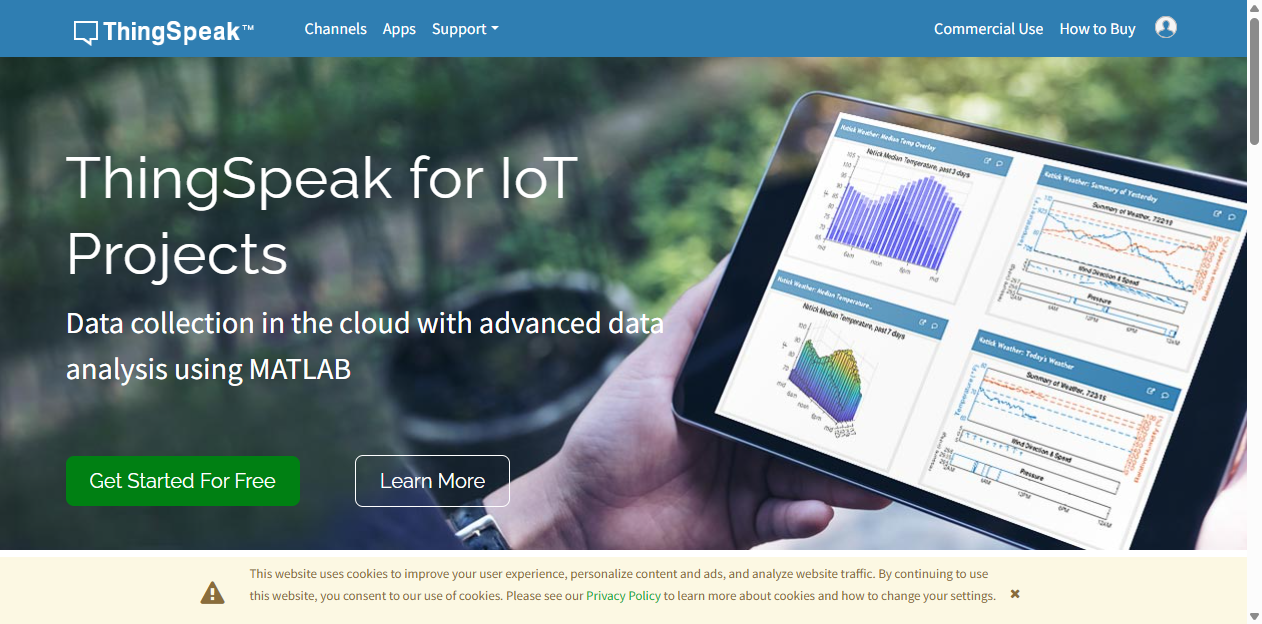

*Gambar 1: Halaman awal ThingSpeak. Dari sini klik ****Sign In**** (kanan atas) atau ****Get Started For Free****.*

- Klik **Sign In**. Jika belum punya akun MathWorks, klik **Create Account** pada halaman sign-in MathWorks dan lengkapi registrasi (nama, email, kata sandi).

- Setelah masuk, Anda tiba di dashboard ThingSpeak.

### 3b. Buat kanal privat

- Dari navigasi atas klik **Channels → My Channels**.

- Klik **New Channel** (atau **+ New Channel**).

- Pada formulir **Channel Settings** isi field kanal **persis seperti Tabel 1** — nama field harus cocok dengan sinyal yang dipublikasikan model.

**Pengaturan · Nilai**

- **Name** — `ESP32MQTT`

- **Description** — `IoT workshop dengan ThingSpeak MQTT dan ESP32`

- **Field 1** — `TemperatureData`

- **Field 2** — `ThresholdData`

- **Field 3** — `FanControl`

- **Field 4–8** — *(biarkan kosong)*

- Klik **Save Channel**.

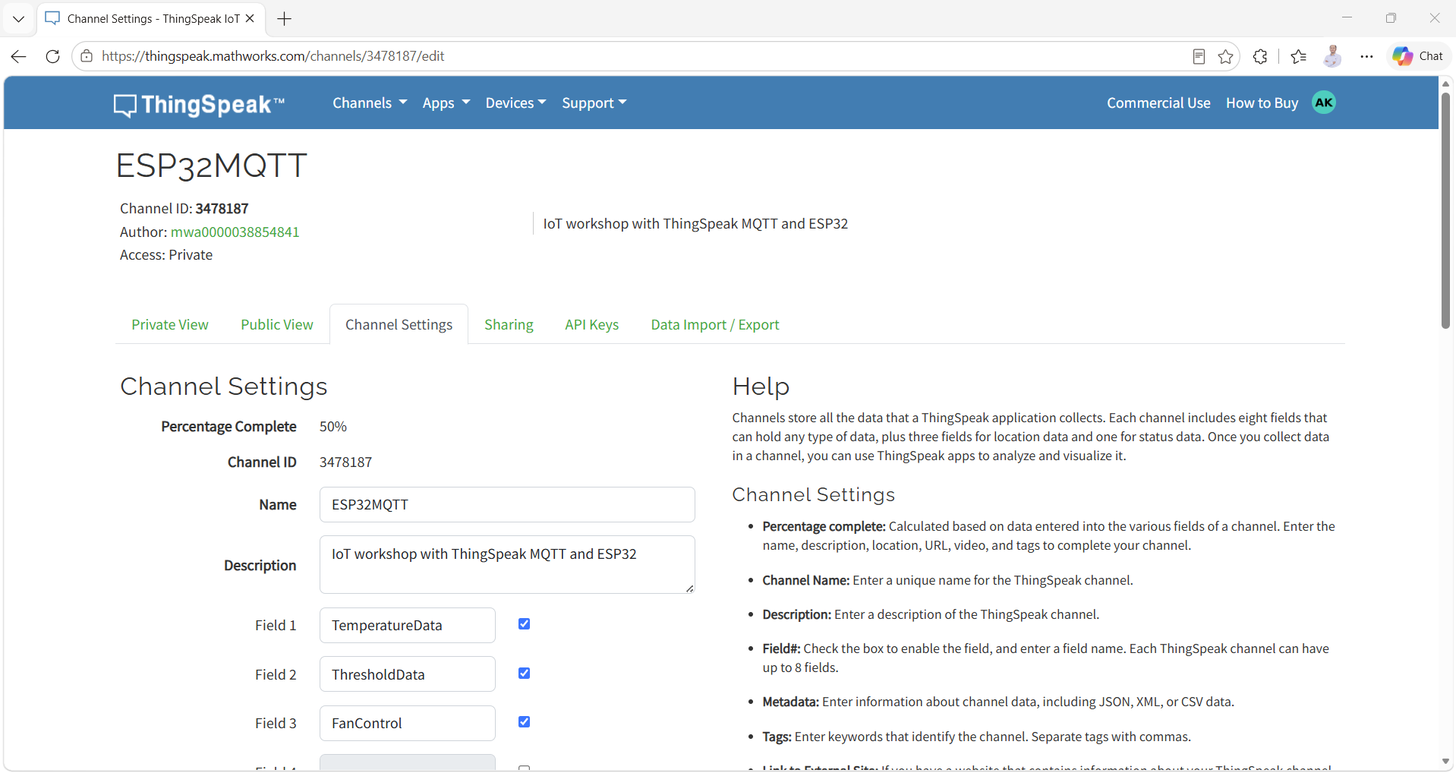

*Gambar 2: Halaman Channel Settings setelah disimpan — Field 1 = TemperatureData, Field 2 = ThresholdData, Field 3 = FanControl.*

### 3c. Kumpulkan empat kredensial

Buka kanal (**Channels → My Channels → kanal Anda**), lalu buka tab **API Keys**.

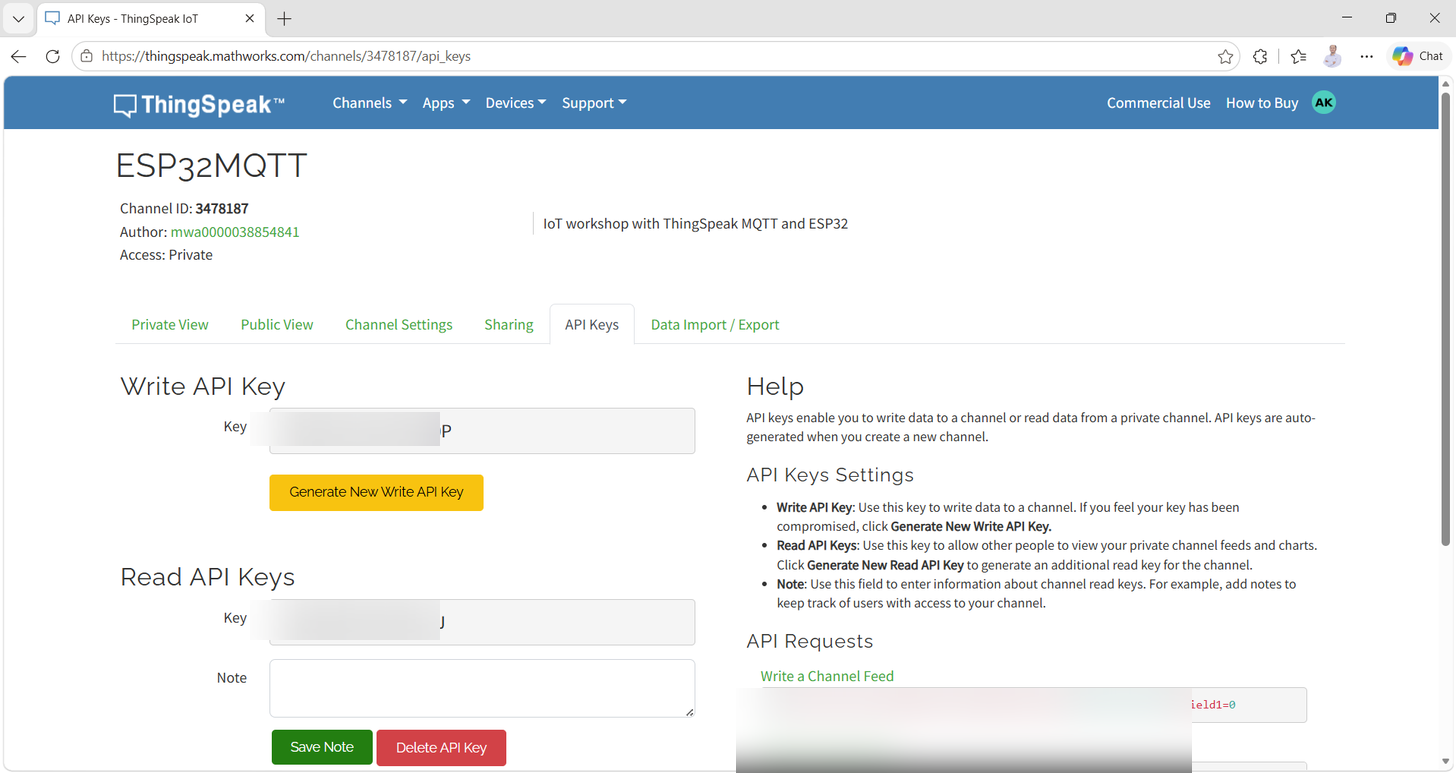

*Gambar 3: Tab API Keys menampilkan Write API Key, Read API Key, dan contoh REST/MQTT. Nilai kunci kanal demo ****dikaburkan**** demi privasi; kanal Anda sendiri akan menampilkan kunci masing-masing.*

Catat kredensial berikut untuk Langkah 3/4 — akan Anda masukkan ke model Simulink:

**Kredensial · Di mana menemukannya · Nilai kanal demo (referensi saja)**

- **Channel ID** — Header kanal · `3478187`

⚠️ **Jaga kerahasiaan kunci.** Write key memungkinkan siapa pun menulis ke kanal Anda. Gunakan kunci Anda sendiri di model — jangan pernah men-commit kunci milik orang lain.

🎤 **Narasi (presenter):** "Perhatikan nama field — `TemperatureData`, `ThresholdData`, `FanControl`. Itu bukan sekadar label. ThingSpeak menyimpan tiap nilai pada field bernomor, dan model menyusun pesan `field1=…&field2=…&field3=…` yang persis cocok dengan kanal ini. Salah penulisan nama, data masuk ke field yang keliru."

## 4. Langkah 2 — Jelajahi Model Starter (~5 menit)

>> open_system('models/SimulinkIoTThingSpeak_starter.slx')


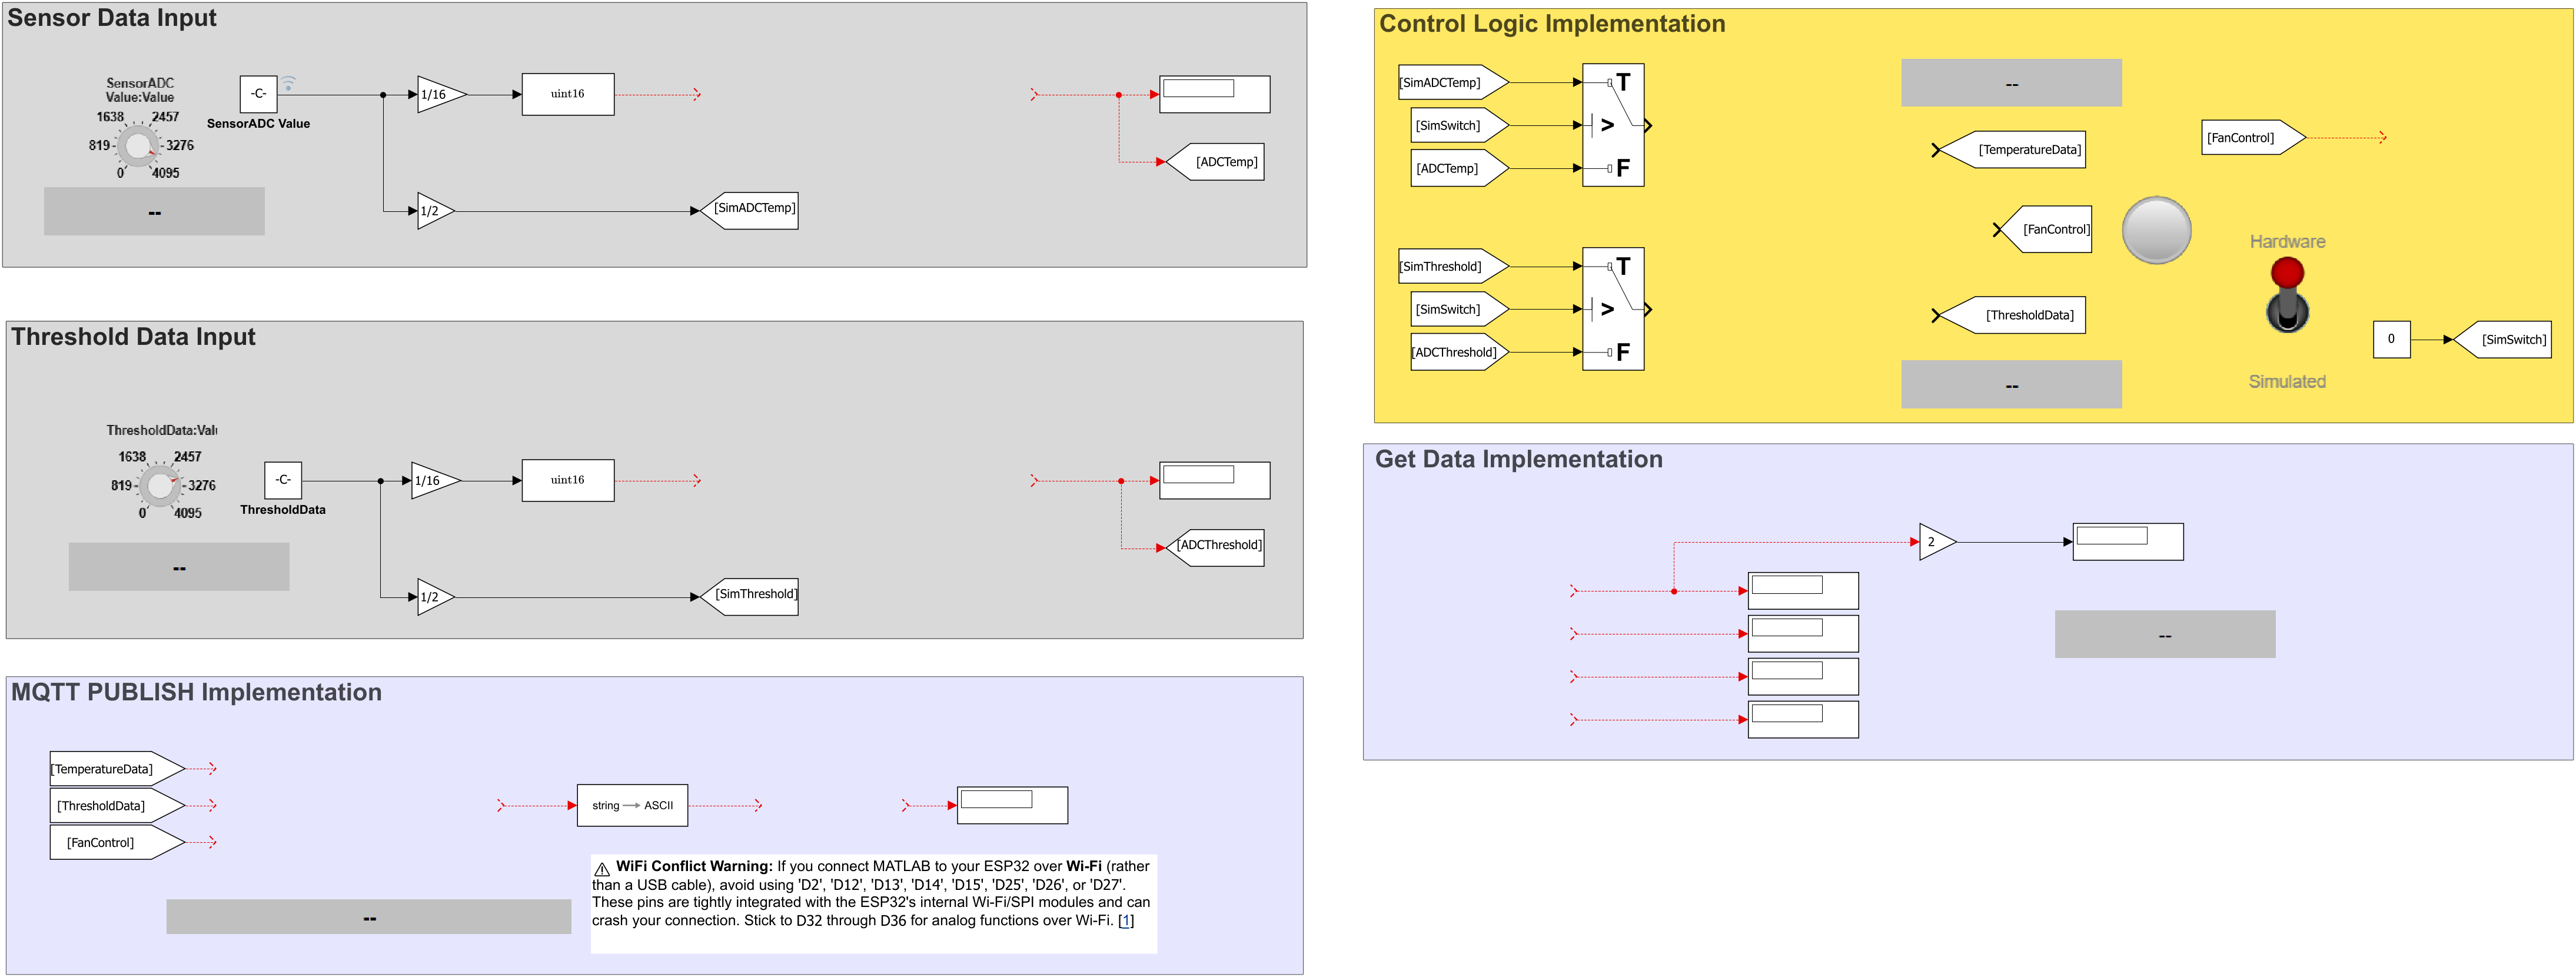

*Gambar 4: ****Model starter**** terbuka dengan kerangka simulasi yang sudah terpasang — knob dashboard, pemilih sumber Sim/HW, konstanta threshold, routing sinyal GoTo/From, dan display.*

Model starter sudah berisi (hanya dibaca pada langkah ini):

- **Knob / Knob1** — input dashboard (`ScaleMax = 4095`, sesuai ADC 12-bit ESP32).

- **SensorADC Value** dan **ThresholdData** (konstanta, `±3620` / `±2951` di starter) — nilai *simulasi* yang diatur knob. Di model **lengkap**, keduanya menjadi **parameter tunable** `SensorKnob` / `ThresholdKnob` (didefinisikan di `data/TunableParameter.m`).

- **Sensor Data Source** — komponen web custom tuning (toggle Sim ↔ Hardware).

- **Switch / Switch2** — memilih input **Simulasi** (dari knob) atau **Hardware** (dari ADC ESP32, ditambahkan di Langkah 4).

- **Blok GoTo/From** — tag `SimADCTemp`, `SimThreshold`, `ADCTemp`, `ADCThreshold`, `TemperatureData`, `ThresholdData`, `FanControl` mengangkut sinyal di antara dua sisi model.

- **Display & Lamp** — memvisualisasikan nilai hasil scaling dan status on/off.

🎤 **Narasi (presenter):** "Model starter adalah jalur kabel — semua *pipa* sudah terpasang. Perhatikan tag `GoTo`/`From`: ia bekerja seperti bus bernama sehingga kita bisa merutekan sinyal tanpa menggambar setiap kabelnya. Tugas Anda sekarang adalah menambahkan *mesinnya*: input ADC asli, logika threshold, dan blok IoT yang berkomunikasi dengan ThingSpeak."

## 5. Langkah 3 — Konfigurasi Target ESP32 (~5 menit)

Buka **Model Settings** (**Ctrl+E**) dan periksa pengaturan berikut:

**Tab · Pengaturan · Nilai**

- **Solver** — Type · `Fixed-step`

- **Solver** — `discrete (no continuous states)`; Fixed-step size `auto`

- **Hardware Implementation** — Hardware board · `ESP32-WROOM (Arduino Compatible)`

- **Sample time** — `0.01` (dari blok Analog Input)

- **Hardware Implementation → Target hardware resources → External mode** — Configuration · `XCP on Serial`

- **COM port** — port `arduinolist` Anda (mis. `COM8`)

- **Baud rate** — `921600`

- **Hardware Implementation → Target hardware resources → Wi-Fi** — SSID · nama access point Anda

- **Password (WPA)** — kata sandi Wi-Fi Anda

- **Hardware Implementation → Target hardware resources → ThingSpeak / MQTT** — Channel ID · Channel ID Anda

- **Write / MQTT API key** — kunci Anda sendiri

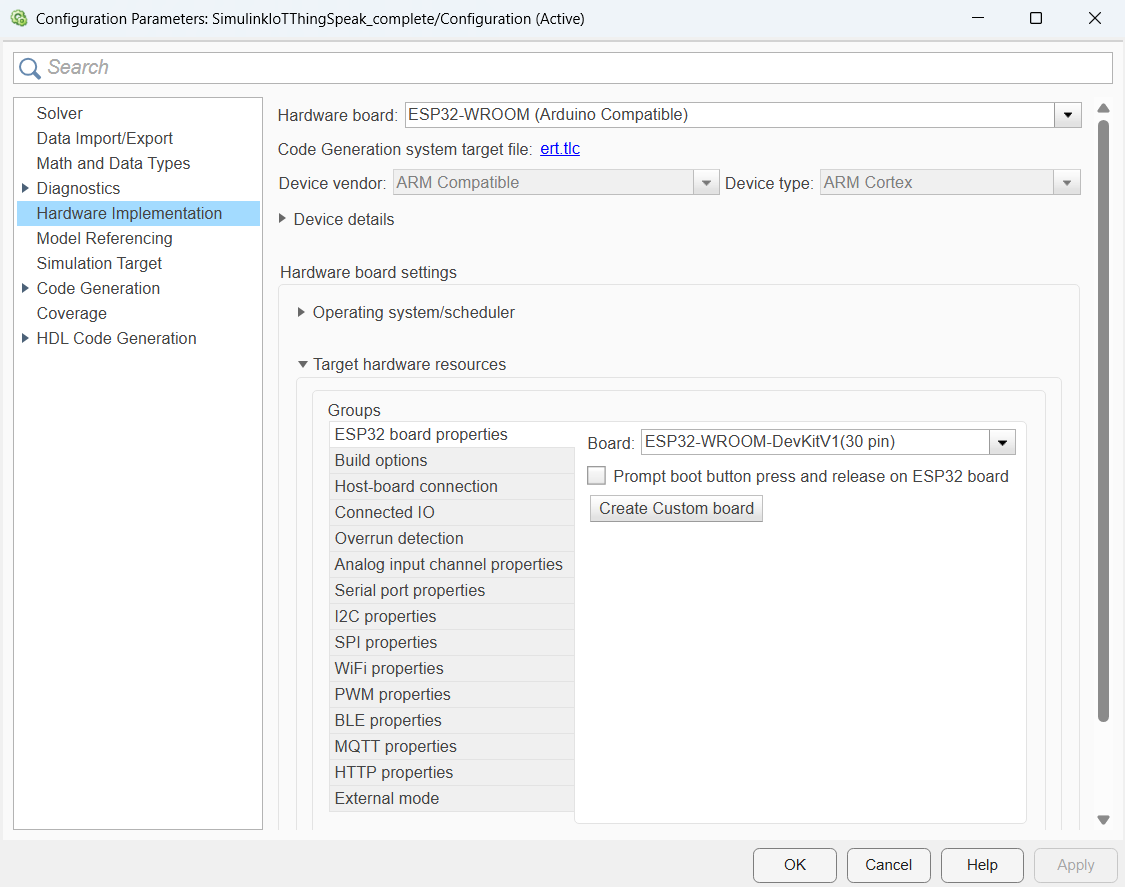

*Gambar 5: ****Model Settings → Hardware Implementation**** (dibuka dengan *`Ctrl+E`*). Board ESP32-WROOM (Arduino Compatible), target code-generation *`ert.tlc`*, dan target hardware resources (Wi-Fi, external mode) dikonfigurasi di sini.*

**Optimisasi code-generation (Model Settings → Code Generation → Optimization):**

- **Default parameter behavior** = `Inlined` (parameter di-inline; `RTWInlineParameters = on`, akses **Literals**).

- **Parameter tunable** — `SensorKnob` dan `ThresholdKnob` adalah objek `Simulink.Parameter` dengan penyimpanan `ExportedGlobal`, didefinisikan di `data/TunableParameter.m` (`SensorKnob.Value = 3072`, `ThresholdKnob.Value = 2048`). Karena tunable, keduanya dapat diubah **live** pada mode external (Monitor & Tune) tanpa rebuild — knob dashboard menggerakkannya.

- **Level optimisasi** = standar (`OptimizationPriority` `Balanced`); optimisasi penyimpanan buffer dan block-I/O nonaktif — menjaga kode yang dihasilkan tetap sederhana dan mudah dibaca.

💡 Model lengkap dikirim dengan kredensial **placeholder** (`YOUR_WIFI_SSID`, `YOUR_WIFI_PASSWORD`, `YOUR_MQTT_USERNAME`, `YOUR_MQTT_PASSWORD`, `YOUR_READ_API_KEY`). **Ganti dengan Wi‑Fi dan kanal milik Anda sendiri** agar data mengalir ke akun ThingSpeak *Anda* — dialog blok dan pengaturan target membaca nilai-nilai ini saat build.

## 6. Langkah 4–7 — Bangun Blok IoT & Hardware (~40 menit)

Semua blok di bawah ini ada di **model lengkap** (`models/SimulinkIoTThingSpeak_complete.slx`). Tambahkan ke starter dan hubungkan ke tag GoTo/From yang sudah ada.

### Langkah 4: Analog input + loop-back DAC

Dari library **Simulink Support Package for Arduino** (`arduinolib`) tambahkan:

- Dua blok **Analog Input**.

- Pengaturan: **Pin = 4** dan **Pin = 5** (pin ADC tempat sensor terhubung); **Sample time = 0.01**; output `uint16`.

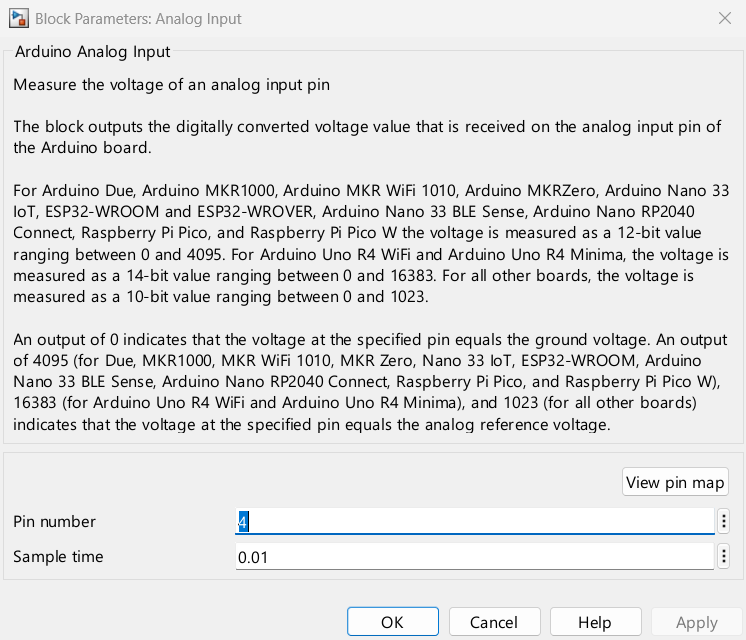

*Gambar 6: Dialog ****Analog Input**** — ****Pin = 4**** untuk sensor temperatur, ****Sample time = 0.01****, output *`uint16`*.*

- Hubungkan (melalui **Gain** `1/16` dan **Data Type Conversion** ke `uint16`) ke tag GoTo `ADCTemp` / `ADCThreshold`, sehingga blok **Switch** dapat memilihnya pada mode Hardware.

- Tambahkan dua blok **Analog Output** dan atur pin-nya ke **DAC1** dan **DAC2**. Hubungkan nilai ADC hasil scaling ke blok ini — ini membuat **loop-back ADC → DAC** nyata pada ESP32: putar potensiometer dan tegangan output DAC mengikutinya.

🔑 **Mengapa 1/16?** ADC ESP32 menghasilkan 0–4095 (12-bit). `4096 ÷ 256 = 16`, sehingga `Gain = 1/16` memetakan rentang ADC penuh ke rentang DAC 8-bit (0–255) — tanpa saturasi, jangkauan penuh.

### Langkah 5: Publikasi ke ThingSpeak melalui MQTT

Model menyusun string payload lalu mempublikasikannya setiap 60 detik.

- Tambahkan blok **Compose String**. Pada dialognya atur:

- **Format** = `field1=%d&field2=%d&field3=%d`

- **Inputs**: hubungkan `From_TemperatureData` → input 1, `From_ThresholdData` → input 2, `From_FanControl` → input 3.

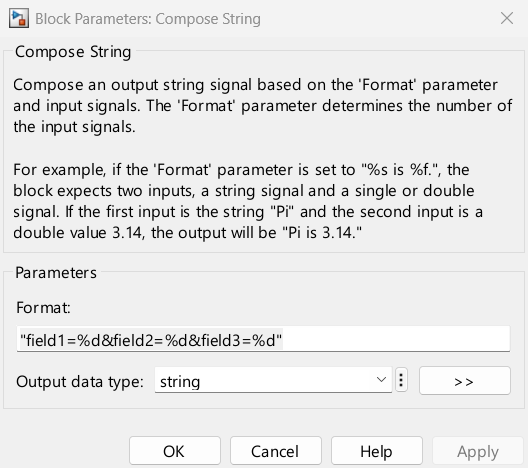

*Gambar 7: Dialog ****Compose String**** — parameter *`Format`* adalah template payload ThingSpeak *`field1=%d&field2=%d&field3=%d`*.*

- Model starter sudah memiliki blok **String to ASCII** (ukuran vektor output `128`). Hubungkan output Compose String ke blok ini — MQTT mengirim payload sebagai vektor byte ASCII.

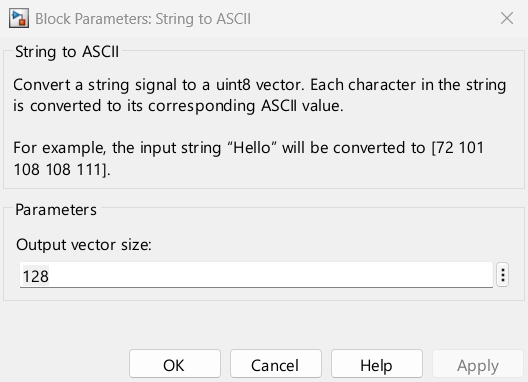

*Gambar 8: Dialog ****String to ASCII**** — ****Output vector size*** `128`*.*

- Tambahkan blok **WiFi MQTT Publish** (`arduinowifilib`) dan atur:

- **Broker service** = `ThingSpeak`

- **Topic** = `channels/<CHANNEL_ID_ANDA>/publish`

- **Update interval** = `60` (detik)

- Hubungkan output `String to ASCII` ke inputnya. Hubungkan **Output** ke **Display** (menampilkan status / kode error publish).

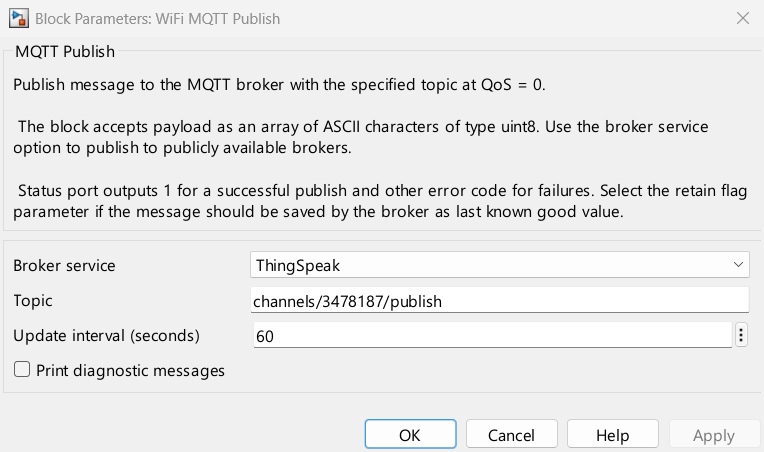

*Gambar 9: Dialog ****WiFi MQTT Publish**** — Broker service = *`ThingSpeak`*, ****Update interval**** = *`60`* detik.*

📡 Blok menggunakan kredensial **Wi-Fi** dan **MQTT ThingSpeak** yang Anda atur di **Langkah 3** (Model Settings → Target hardware resources). Broker MQTT ThingSpeak adalah `mqtt3.thingspeak.com`, port `1883`; blok menjaga koneksi persisten dan mempublikasikan sesuai interval.

### Langkah 6: Logika fan / aktivitas (threshold)

- Tambahkan **Relational Operator** dan atur **Operator = **`>`.

- **Input 1**: `TemperatureData` · **Input 2**: `ThresholdData`.

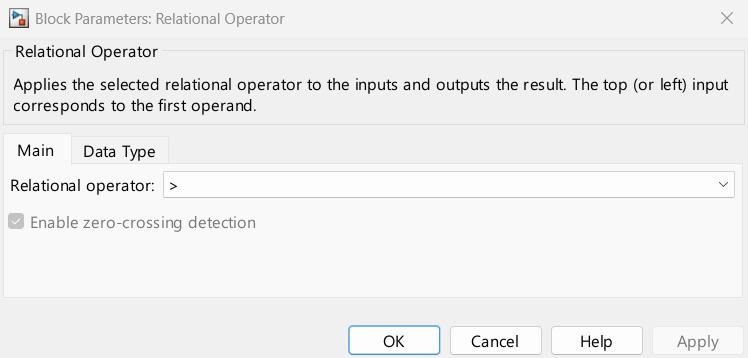

*Gambar 10: Dialog ****Relational Operator**** — Operator = *`>`*. Input 1 = TemperatureData, Input 2 = ThresholdData.*

- Hubungkan outputnya (`boolean`) ke tag GoTo **FanControl**. Sinyal ini sudah dirutekan ke:

- **Compose String** (Field 3) — sehingga status on/off ikut dipublikasikan; dan

- `From_FanControl` → blok **Digital Output** pada **Pin 2** — menggerakkan LED/buzzer di board.

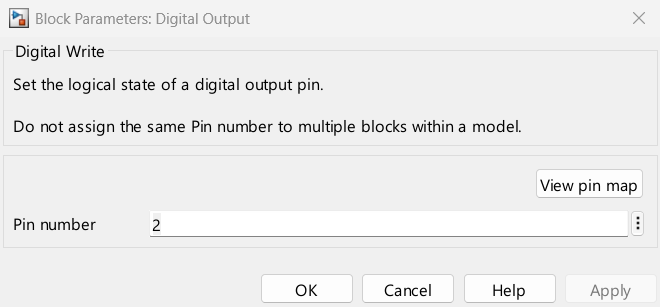

*Gambar 11: Dialog ****Digital Output**** — ****Pin number*** `2`* (output fan/aktivitas di board).*

Ketika `TemperatureData > ThresholdData`, `FanControl = 1` dan **D2 menyala**.

### Langkah 7: Baca kembali kanal Anda (loop tertutup)

- Tambahkan blok **WiFi ThingSpeak Read** (`arduinowifilib`) dan atur:

- **Channel ID** = **Channel ID** Anda

- **Interface** = `Wi-Fi`; **Channel access** = `Private`

- **Read API key** = kunci Read Anda

- **Fields to read** = `[1 2 3]`

- **Sample time** = `15` (detik)

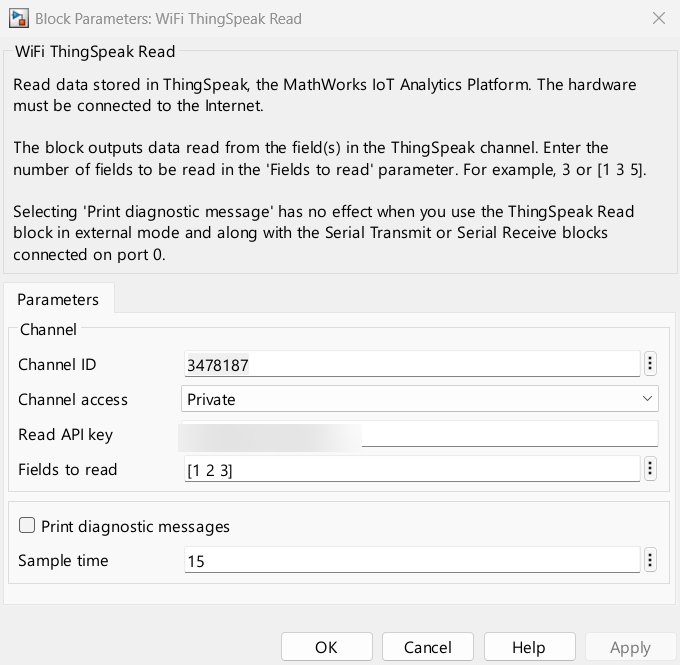

*Gambar 12: Dialog ****WiFi ThingSpeak Read**** — Channel ID, kunci Read, ****Fields to read**** = *`[1 2 3]`*, ****Sample time**** = *`15`* detik.*

- Hubungkan **Outputs 2, 3, 4** ke tiga blok **Display**. Output 1 adalah status permintaan.

Ini memberi Anda loop *read-back*: apa pun yang dipublikasikan ESP32 akan muncul kembali di Display dalam ±15 detik — membuktikan perjalanan pulang-pergi melalui cloud.

### Simpan & update

>> set_param('SimulinkIoTThingSpeak_complete','SimulationCommand','update')
>> save_system('SimulinkIoTThingSpeak_complete')


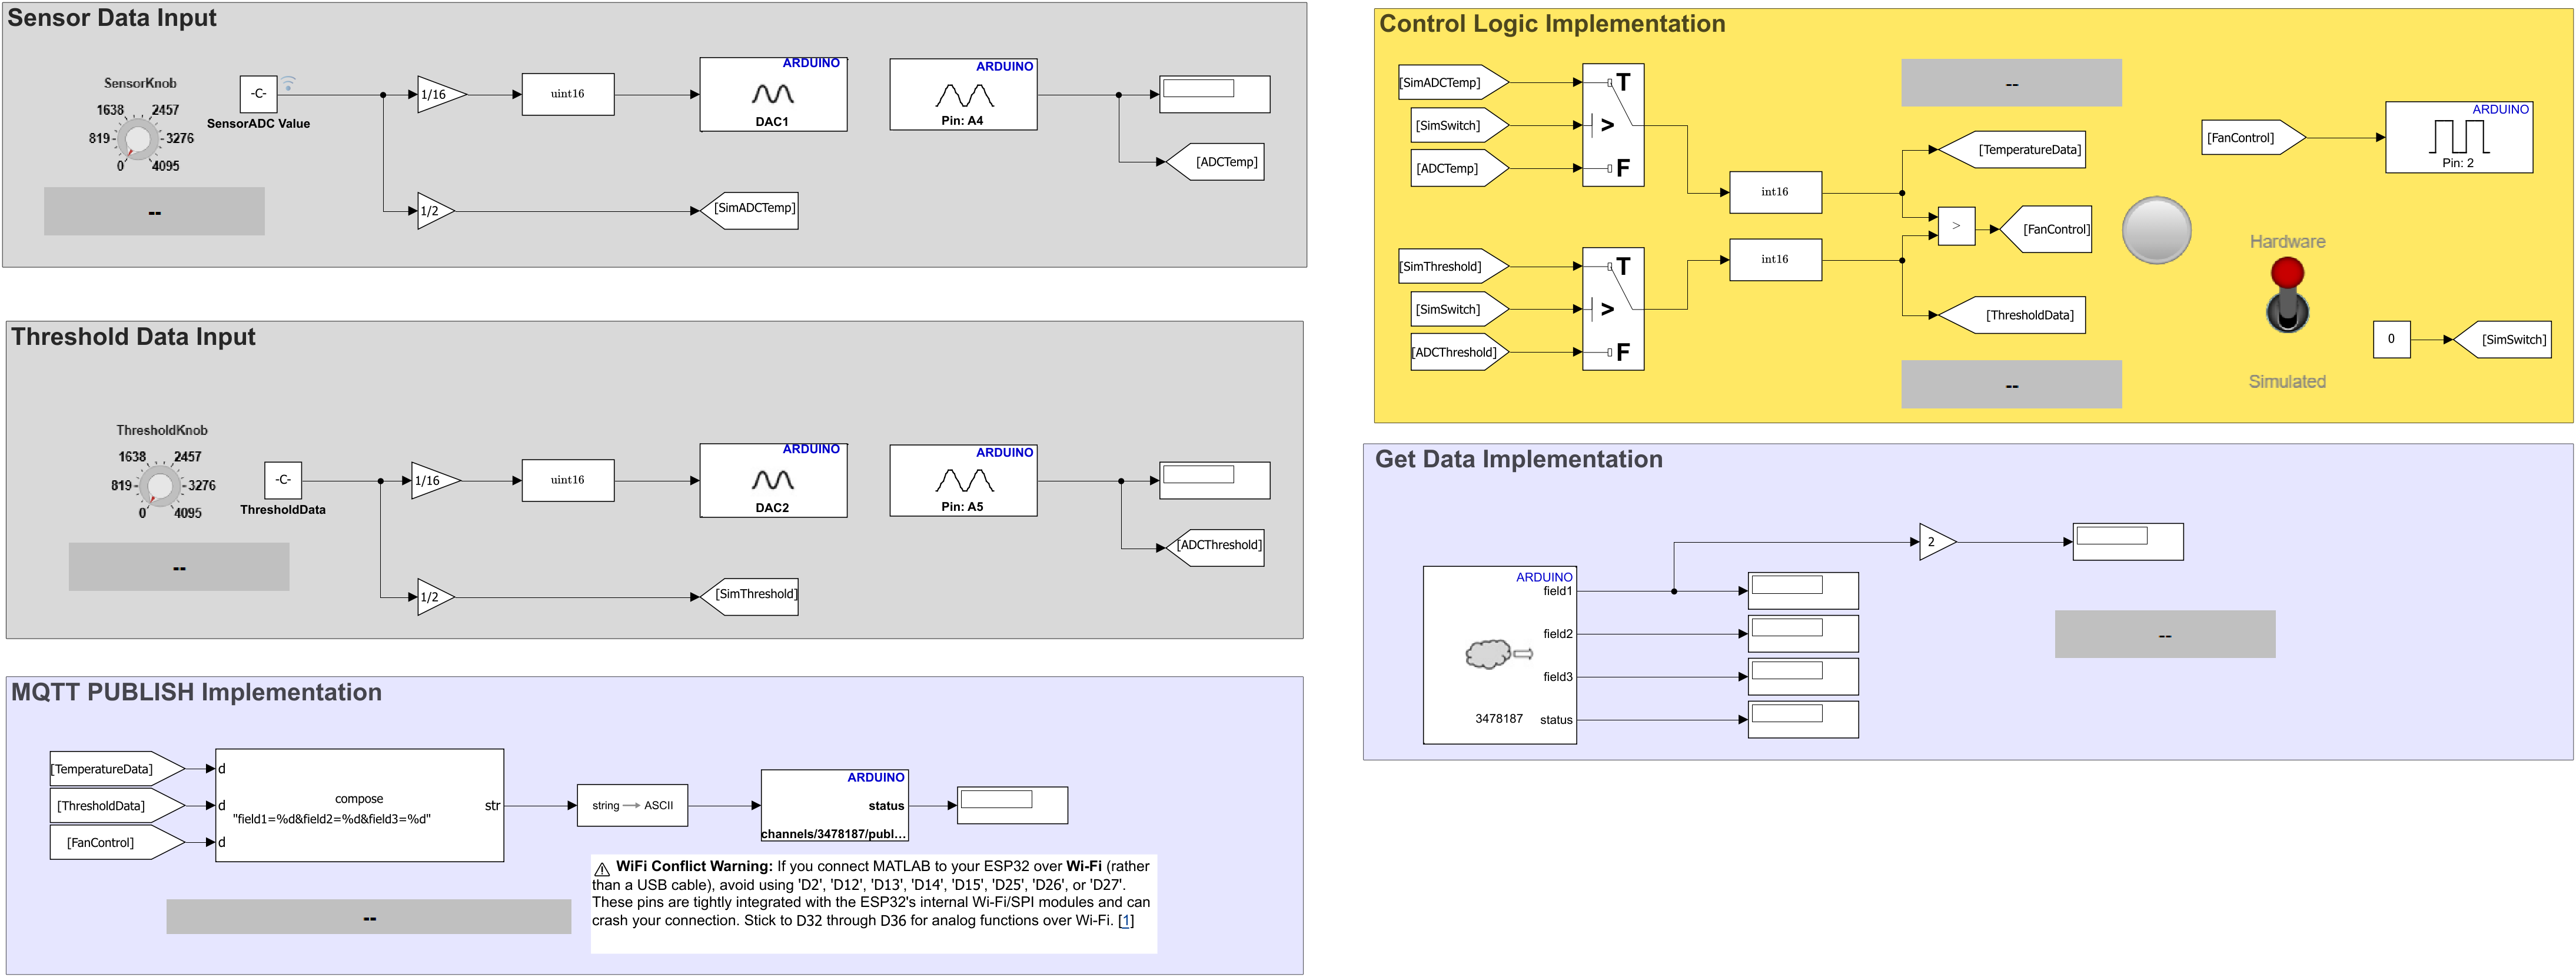

*Gambar 13: ****Model lengkap****. Analog input (ADC)×2 mengisi scaling/loop-back DAC dan switch Sim↔Hardware; rantai Compose String → String to ASCII → MQTT Publish keluar di tengah-atas; Relational Operator menggerakkan FanControl; dan WiFi ThingSpeak Read mengembalikan data kanal sendiri ke display.*

## 7. Langkah 8 — Deploy & Alirkan Data Live (~15 menit)

Karena **external mode** diaktifkan, MATLAB **membangun, mengunggah, dan menjalankan** model di ESP32, lalu memungkinkan Anda **Monitor & Tune** melalui tautan XCP-on-Serial.

### Langkah 8a — Jalankan dengan Monitor & Tune (tab Hardware)

- Pada toolstrip model, buka tab **Hardware**.

- Di grup **Run on Hardware**, klik **Monitor & Tune**.

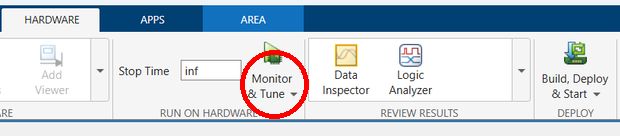

*Gambar 14: Pada tab ****Hardware****, klik ****Monitor & Tune**** (lingkaran merah) — MATLAB membangun, mengunggah, dan menjalankan model di ESP32 dalam external mode.*

⚠️ **Run pertama:** model membaca `SensorKnob` / `ThresholdKnob` dari base workspace. Jika build gagal dengan galat *"undefined variable"*, jalankan `run('data/TunableParameter.m')` terlebih dahulu (Langkah 0), lalu klik **Monitor & Tune** lagi.

MATLAB mengompilasi kode Embedded Coder (ERT), mem-flash ESP32 melalui port COM yang dikonfigurasi, terhubung XCP on Serial, dan aliran data dimulai.

Selama berjalan Anda dapat **Monitor & Tune** secara live:

- Membalik toggle **Sensor Data Source** untuk beralih antara knob **Simulasi** dan input ADC **Hardware**.

- Memutar **Knob / Knob1** untuk mengubah `SensorKnob` / `ThresholdKnob` (`TemperatureData` / `ThresholdData`) secara live — keduanya **parameter tunable** (`ExportedGlobal`), sehingga berubah tanpa rebuild.

- Mengamati **Display** dan **Lamp** bereaksi secara real time.

Sekarang buka **ThingSpeak → Channels → My Channels → kanal Anda → Private View**:

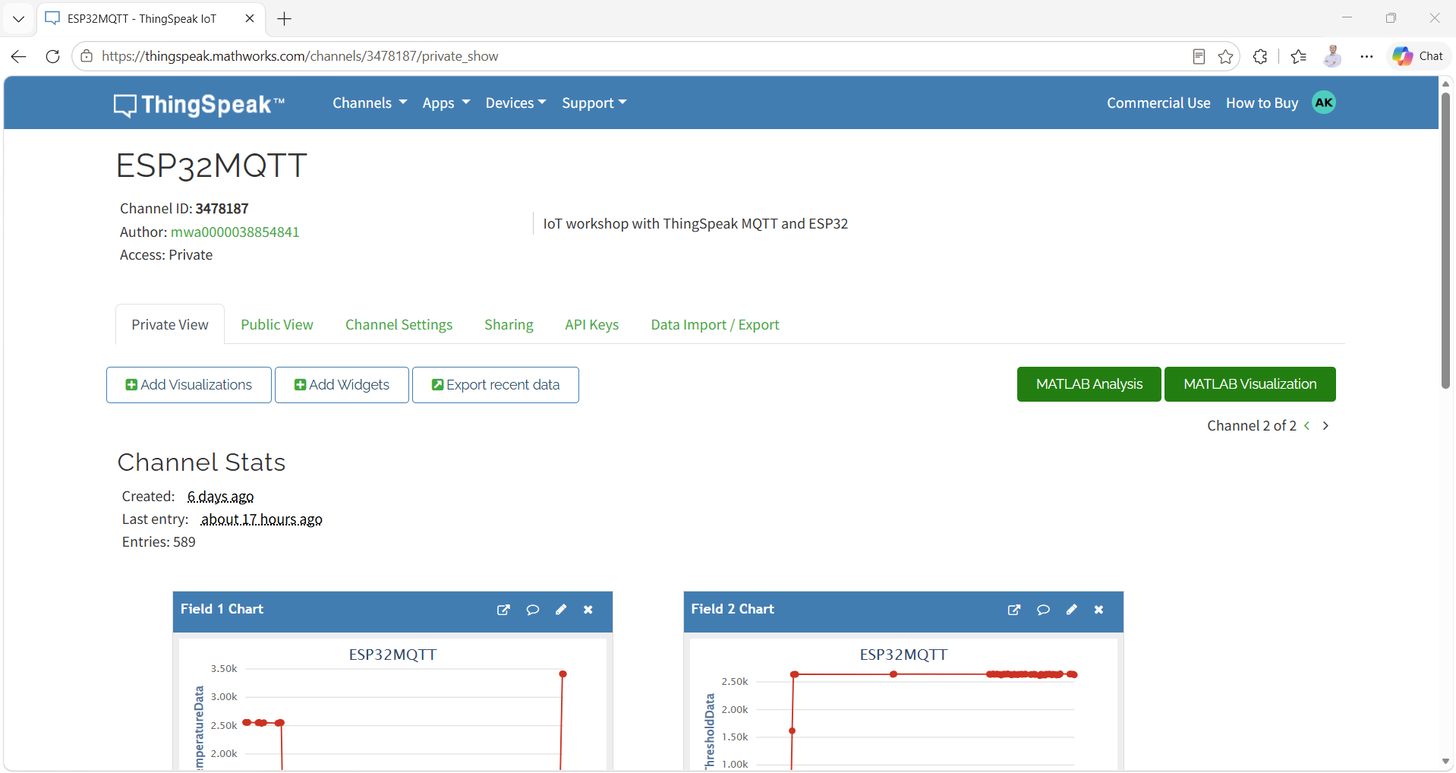

*Gambar 15: Grafik Field 1–3 live pada kanal ThingSpeak setelah ESP32 mulai mempublikasikan. Field 1 = TemperatureData, Field 2 = ThresholdData, Field 3 = FanControl.*

✅ **Kriteria lolos:** dalam ±60 detik setelah **Run**, sampel baru muncul pada grafik **Field 1 dan Field 2**, dan **Field 3** berubah antara `0`/`1` saat Anda melewati threshold dengan knob. **Display** yang diumpan *WiFi ThingSpeak Read* me-refresh nilai yang sama kembali ke model.

🎤 **Narasi (presenter):** "Inilah loop IoT yang terlihat: ESP32 membaca → mempublikasikan lewat MQTT → ThingSpeak menyimpan → model membaca kembali kanalnya sendiri. Jika Anda melihat Field 3 berubah di cloud sambil menarik knob, semua mata rantai bekerja."

## 8. Langkah 9 — Validasi Pemetaan Field

**Sinyal model · Rantai blok · Field ThingSpeak · Ekspektasi di kanal**

- **TemperatureData** — ADC/simulasi → scaling → Compose String input 1 · **Field 1** · nilai ADC ±0–4095

- **ThresholdData** — ADC/simulasi → scaling → Compose String input 2 · **Field 2** · nilai threshold ±0–4095

- **FanControl** — `TemperatureData > ThresholdData` → Compose String input 3 · **Field 3** · `0` atau `1`

Jika ada field kosong atau salah:

- Nama field di kanal harus **persis sama** dengan nama blok/variabel (`TemperatureData`, `ThresholdData`, `FanControl`).

- **Format Compose String** harus `field1=%d&field2=%d&field3=%d`.

- **Topic MQTT** harus `channels/<CHANNEL_ID_ANDA>/publish` (Channel ID Anda, bukan `3478187` milik demo).

## 9. Tantangan (~10 menit)

- **Percepat:** ubah **Update interval** *WiFi MQTT Publish* dari `60` menjadi `30` detik. Jalankan ulang dan amati grafik Field 1 ter-update dua kali lebih cepat. Ingat batas penulisan pada tier gratis ThingSpeak.

## 10. Ringkasan

**Fase · Perintah / Aksi · Poin Kunci**

- **Verifikasi** — `ver('simulink')`, `supportPackageInstaller`, `arduinolist` · Ketahui yang terpasang dan port COM ESP32

- **Setup IoT** — ThingSpeak → My Channels → New Channel · Field bernama + kunci Write/Read/MQTT menggerakkan seluruh model

- **Konfigurasi** — Hardware Implementation → ESP32-WROOM, external mode, Wi-Fi, kredensial ThingSpeak · Satu tempat menyimpan semua kredensial yang dibaca blok saat build

- **Model** — Analog In / DAC, Compose String, MQTT Publish, ThingSpeak Read, komparator `>` · Model hanyalah data-masuk → publish → read-back

- **Deploy** — `SimulationMode = external`, `Ctrl+T` · External (Monitor & Tune) mem-flash dan mengalirkan data live

- **Observasi** — ThingSpeak Private View · Cloud mengonfirmasi loop IoT yang lengkap

### Arsitektur yang Dipelajari

ADC ESP32 / knob dashboard ─▶ TemperatureData, ThresholdData
              │
    TemperatureData > ThresholdData ─▶ FanControl
              │
  Compose String "field1=%d&field2=%d&field3=%d"
              │  (String to ASCII, 128)
              ▼
  WiFi MQTT Publish (ThingSpeak, channels/<ID>/publish, 30 dtk)
              │
              ▼
  Kanal ThingSpeak (Field 1,2,3)  ◀── WiFi ThingSpeak Read (15 dtk) ─▶ Display


## 11. Pemecahan Masalah

**Masalah · Kemungkinan Penyebab · Solusi**

- **arduinolist kosong** — Board belum terhubung / driver · Cabut-tancap USB; cek Device Manager; coba kabel/port lain

- **Port sibuk saat deploy** — Serial Monitor atau MATLAB lain terbuka · Tutup Serial Monitor; pilih COM yang benar di Model Settings

- **Publish WiFi gagal** — SSID / password salah · Masukkan ulang kredensial Wi-Fi di Target hardware resources → Wi-Fi

- **Tidak ada data di kanal** — Channel ID / kunci salah · Verifikasi topic `channels/<ID>/publish` serta kunci Write/MQTT di blok + pengaturan target

- **Field 3 selalu 0** — Wiring operand `>` salah · Pastikan input 1 = TemperatureData, input 2 = ThresholdData; balik operand untuk menguji

- **Field terisi salah** — Nama field tidak cocok nama blok · Ganti nama field kanal persis `TemperatureData`, `ThresholdData`, `FanControl`

- **Output Compose kosong** — Typo format / input · Gunakan `field1=%d&field2=%d&field3=%d` terhubung ke input 1,2,3 berurutan

- **External mode gagal terhubung** — Pengaturan XCP / baud tidak cocok · Atur Configuration = `XCP on Serial`, baud `921600`, COM yang benar

- **Output DAC stuck** — Nilai ADC saturasi · Pastikan `Gain = 1/16` dan Data Type Conversion ke `uint16` (tanpa saturasi overflow)

## 12. Referensi MathWorks

- ThingSpeak — Getting Started (https://www.mathworks.com/help/thingspeak/getting-started-with-thingspeak.html)

- Collect Data in a New Channel (https://www.mathworks.com/help/thingspeak/collect-data-in-a-new-channel.html)

- ThingSpeak Channels & Charts API (https://www.mathworks.com/help/thingspeak/channels-and-charts-api.html)

- Write Data with MQTT (ESP32/ESP8266) (https://www.mathworks.com/help/thingspeak/examples.html?category=write-data)

- Simulink Support Package for Arduino Hardware (https://www.mathworks.com/hardware-support/arduino-simulink.html)

- MATLAB & Simulink + ThingSpeak (https://www.mathworks.com/hardware-support/thingspeak.html)

*Dibuat untuk Workshop Hands-On · TechSource Systems*